# **Report **on efficiency dispatching taxis

## Mission of the project

**The goal of this study is demand prediction around Manhattan (Low Manhattan, Midtown, Upper East Side, Upper West Side ) and the airports (JFK and LaGuardia) for SUPER TAXIS. The demand has to be predicted as "low", "medium", or  "high" using historical information on revenue and costs available for each region registrated on 2015.**

**To create a predictive model the following stages will be done, namely:**

- **import, clearning, and explore of the 2015 taxi data of SUPER TAXIS;**

- **agregation of pick-ups and drop-offs into six regions;**

- **summary table of pick-ups and drop-offs totals by region and hour;**

- **initial analysis of summary table, structural selection of a predictive model (definition of independent variables);**

## Preprocessing 

In this study we will use data registrated in 2015. 

As a first step we will create a datastore and agregate the data from the separated files into one table. 

listing = dir("Project\TaxiProject05.mlx")

listing = struct with fields:
       name: 'TaxiProject05.mlx'
     folder: 'C:\Users\darya\Desktop\Project'
       date: '27-Oct-2023 15:21:51'
      bytes: 2199291
      isdir: 0
    datenum: 7.3919e+05


pathToSave=listing.folder

pathToSave = 'C:\Users\darya\Desktop\Project'

### Datastore

dataPath = fullfile(fileparts(which('yellow_tripdata_2015-01.csv'))); 
if isempty(dataPath)
    f = msgbox(["Taxi data not found on the MATLAB path." ; ...
        "Please select the location in the following dialog."])
    uiwait(f)
    dataPath = uigetdir([],"Select the folder containing the taxi data.")
end
ds = fileDatastore( fullfile(dataPath,"yellow*.csv"),"ReadFcn", ...
    @importTaxiDataWithoutCleaning,"UniformRead",true);

### Data agregation

reset(ds);
numFiles=size(ds.Files,1);
fileNum=0;
TaxiData=table;
while hasdata(ds)
    data=read(ds);
    data=addTaxiZones(data);
    TaxiData=[TaxiData;data]; %#ok<AGROW> 
    fileNum = fileNum+1; 
    disp("Finished file " + fileNum + " of " + numFiles); 
end

Finished file 1 of 12
Finished file 2 of 12
Finished file 3 of 12
Finished file 4 of 12
Finished file 5 of 12
Finished file 6 of 12
Finished file 7 of 12
Finished file 8 of 12
Finished file 9 of 12
Finished file 10 of 12
Finished file 11 of 12
Finished file 12 of 12


% Save the data to TaxiDataStore.mat
pathToSave='C:\Users\darya\Desktop\Project';
save TaxiDataStore TaxiData pathToSave
clear all %#ok<CLALL> 

%Open processed table with data
load TaxiDataStore.mat TaxiData  %load('C:\Users\Darya\Desktop\MatLab Project\Project\TaxiDataStore.mat','TaxiData')

### Regions definition

**The goal is demand prediction around Manhattan (Low Manhattan, Midtown, Upper East Side, Upper West Side ) and the airports (JFK and LaGuardia) for SUPER TAXIS. **Now we define four custom regions in Manhattan and two airports.

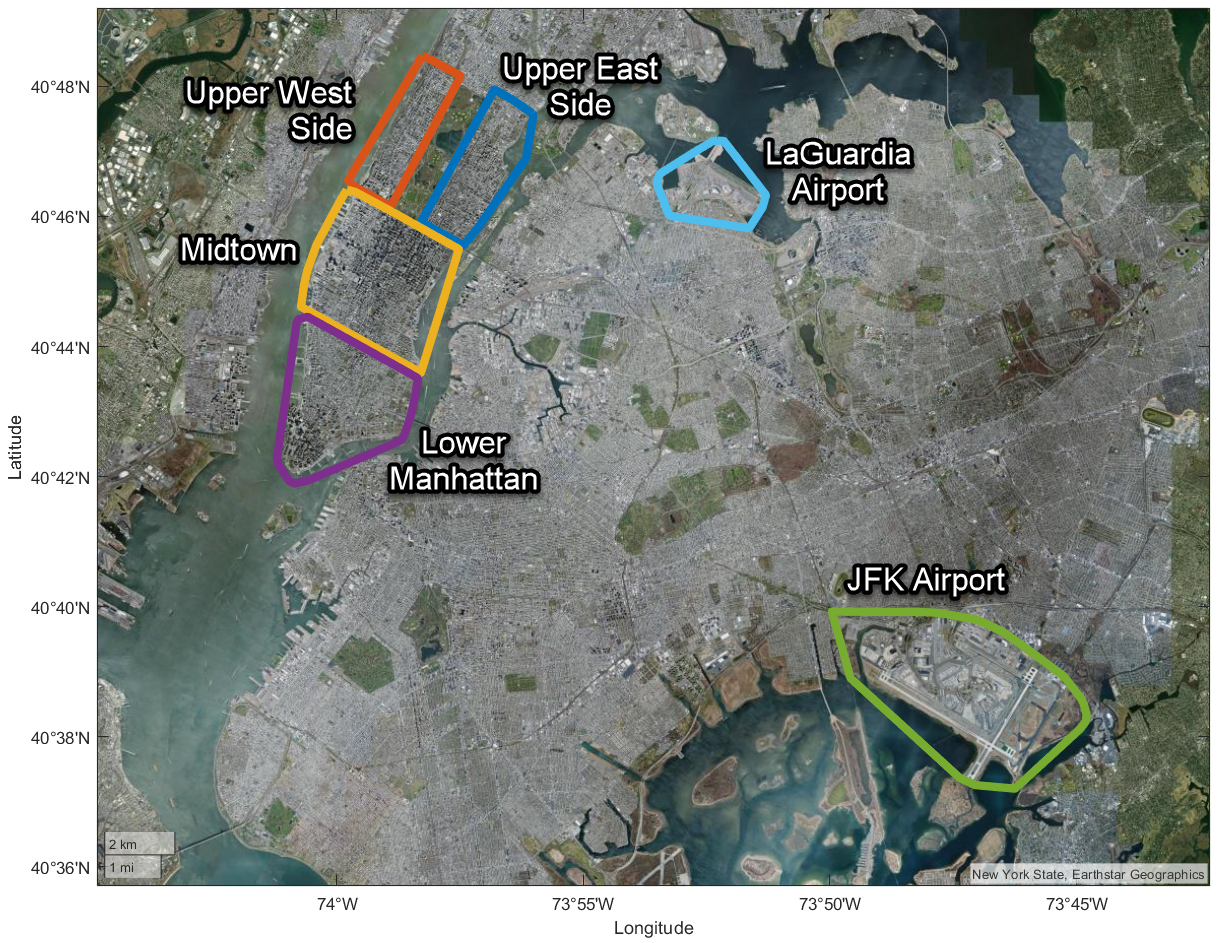

% New variables
H1=height(TaxiData);
TaxiRegionsandZones= importTaxiRegZones('Taxi_Regions_and_Zones.csv');
Zones=categorical(TaxiRegionsandZones.Properties.VariableNames');

Zone1=categorical(TaxiRegionsandZones.LowerManhattan(TaxiRegionsandZones.LowerManhattan~=""));
Zone2=categorical(TaxiRegionsandZones.Midtown(TaxiRegionsandZones.Midtown~=""));
Zone3=categorical(TaxiRegionsandZones.UpperEastSide(TaxiRegionsandZones.UpperEastSide~=""));
Zone4=categorical(TaxiRegionsandZones.UpperWestSide(TaxiRegionsandZones.UpperWestSide~=""));
Zone5=categorical(TaxiRegionsandZones.JFKAirport(TaxiRegionsandZones.JFKAirport~=""));
Zone6=categorical(TaxiRegionsandZones.LaGuardiaAirport(TaxiRegionsandZones.LaGuardiaAirport~=""));
clear TaxiRegionsandZones;

TaxiData.PickupRegion(find(ismember(TaxiData.PickupZone,Zone1)))=Zones(1);
TaxiData.PickupRegion(find(ismember(TaxiData.PickupZone,Zone2)))=Zones(2);
TaxiData.PickupRegion(find(ismember(TaxiData.PickupZone,Zone3)))=Zones(3);
TaxiData.PickupRegion(find(ismember(TaxiData.PickupZone,Zone4)))=Zones(4);
TaxiData.PickupRegion(find(ismember(TaxiData.PickupZone,Zone5)))=Zones(5);
TaxiData.PickupRegion(find(ismember(TaxiData.PickupZone,Zone6)))=Zones(6);

%create new variable DropOffRegion
TaxiData.DropOffRegion(find(ismember(TaxiData.DropoffZone,Zone1)))=Zones(1);
TaxiData.DropOffRegion(find(ismember(TaxiData.DropoffZone,Zone2)))=Zones(2);
TaxiData.DropOffRegion(find(ismember(TaxiData.DropoffZone,Zone3)))=Zones(3);
TaxiData.DropOffRegion(find(ismember(TaxiData.DropoffZone,Zone4)))=Zones(4);
TaxiData.DropOffRegion(find(ismember(TaxiData.DropoffZone,Zone5)))=Zones(5);
TaxiData.DropOffRegion(find(ismember(TaxiData.DropoffZone,Zone6)))=Zones(6);

%We keep "other" region for Pick-up and Dropp-off
TaxiData.PickupRegion(ismissing(TaxiData.PickupRegion),:)='other';
TaxiData.DropOffRegion(ismissing(TaxiData.DropOffRegion),:)='other';

- **the exclusion of the "other-other" pick-up-drop-off region (it is out of the interest of this study)**


TaxiData=TaxiData(~(TaxiData.DropOffRegion=="other" & TaxiData.PickupRegion=="other"),:); %#ok<*NASGU> 
%percent to be excluded
fprintf('There were substructed %f percent of data',(1-height(TaxiData)/H1)*100);

There were substructed 4.652828 percent of data

% listing = dir("TaxiProject.mlx");
pathToSave='C:\Users\darya\Desktop\Project';
save TaxiDataForCleaning TaxiData pathToSave

%clean Workspace
clear Zone1 Zone2 Zone3 Zone4 Zone5 Zone6

### Cleaning taxi dataset

This stage contains several operations: 

- **the basic preprocessing**

h1=height(TaxiData);
H1=h1;
TaxiData = basicPreprocessing(TaxiData);
TaxiData = removevars(TaxiData, {'PickupLon','PickupLat','DropoffLon', ...
    'DropoffLat','PickupZone','DropoffZone'});
TaxiData = removevars(TaxiData, {'Vendor','HeldFlag','ExtraCharge', ...
    'Tax','Tip','Tolls','ImpSurcharge','tzPickupBorough','tzDropoffBorough'});

- **the exclusion of all the trips where the  fare  for a  trip  was less than $2.50**

TaxiData = TaxiData(TaxiData.Fare >= 2.5,:);
h2=height(TaxiData);
fprintf('There were substructed %f percent of data',(1-h2/h1)*100);

There were substructed 1.815850 percent of data

clear h1 h2 listing
save TaxiDataBasicProcessing TaxiData pathToSave

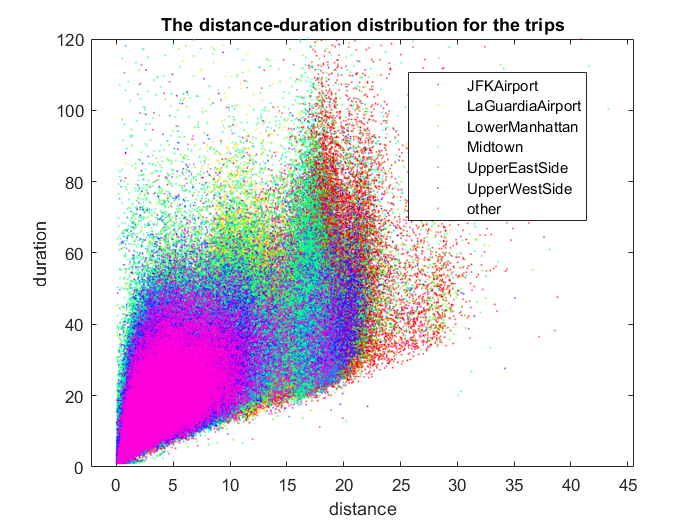

gscatter(TaxiData.Distance,TaxiData.Duration,TaxiData.PickupRegion,[],'.',1)
xlabel('distance')
ylabel('duration')
title('The distance-duration distribution for the trips')

**Several additional procedures will be completed to reduce the uncertanity related to "human-error" or "extreme-road" conditions as traffic intencity or weather conditions**

- **traffic tempo - The NYC citywide maximum limit is 25mph (40 km/h) unless otherwise posted. The limit out the city is 55 mph (88 km/h)**

TaxiData.IsInCity=double(ismember(TaxiData.PickupRegion,{'LowerManhattan','Midtown','UpperEastSide','UpperWestSide'})+ismember(TaxiData.DropOffRegion,{'LowerManhattan','Midtown','UpperEastSide','UpperWestSide'}));
TaxiData=TaxiData(~((TaxiData.AveSpeed>40 & TaxiData.IsInCity==2)| ...
    (TaxiData.AveSpeed>64 & TaxiData.IsInCity==1)| ...
    (TaxiData.AveSpeed>88 & TaxiData.IsInCity==0)),:); %speed limits
TaxiData=TaxiData(~(TaxiData.AveSpeed<2),:);

- **We suppose that duration depends on distance. This non-linear dependence is influenced by region (the day-time conditions in the central part are different from that in the night-time, the trips to airports are longer in distance but not obligatory longest in duration, the different rates are fixed for different directions). Therefore, the distance-duration distribution is a mixture of several other distributions. To separate them we will apply the cluster analysis. First, we will fit the Gaussian mixture model for three clusters. We will call them: "long-distance" - Category1, "medium-distance" - Category2, and "short-distance" - Category3. This gives the possibility to assign probabilities to data points and exclude all the points with negligible probability. Thus, if the probability of a trip is negligible, it is not important how much it costs.**

rng(10); % For reproducibility
gmmN=[TaxiData.Distance,TaxiData.Duration];
gmN=fitgmdist(gmmN,3);

TaxiData.idxDistance=cluster(gmN,gmmN);
TaxiData.idxN=categorical(TaxiData.idxDistance);
tab=groupsummary(TaxiData,"idxN","mean","Distance");
tab = sortrows(tab,'mean_Distance','descend');
D={char(tab.idxN(1));char(tab.idxN(2));char(tab.idxN(3))};
TaxiData.idxN=reordercats(TaxiData.idxN,D);
TaxiData.idxN=renamecats(TaxiData.idxN,{'long','medium','short'});
TaxiData.PDF1=pdf(gmN,gmmN);
TaxiData=TaxiData(TaxiData.PDF1>2.5e-07,:);

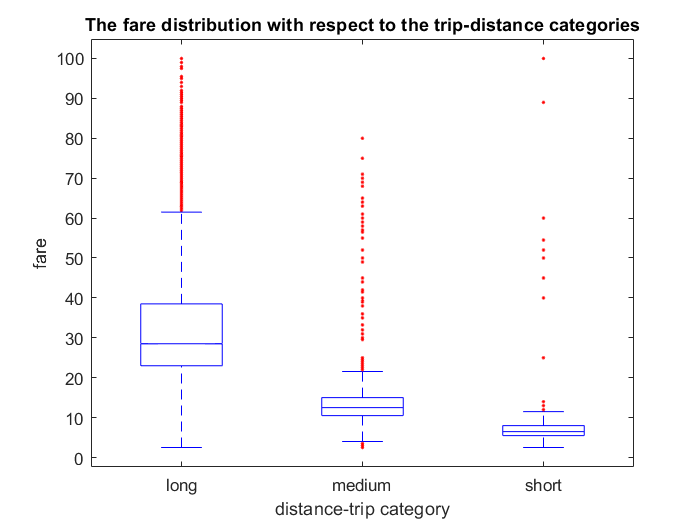

boxplot(TaxiData.Fare,TaxiData.idxN,'Notch','on',"OutlierSize",5,"Colors","b","BoxStyle", ...
    "outline","Symbol",'r.')
xlabel('distance-trip category');
ylabel('fare');
title('The fare distribution with respect to the trip-distance categories')

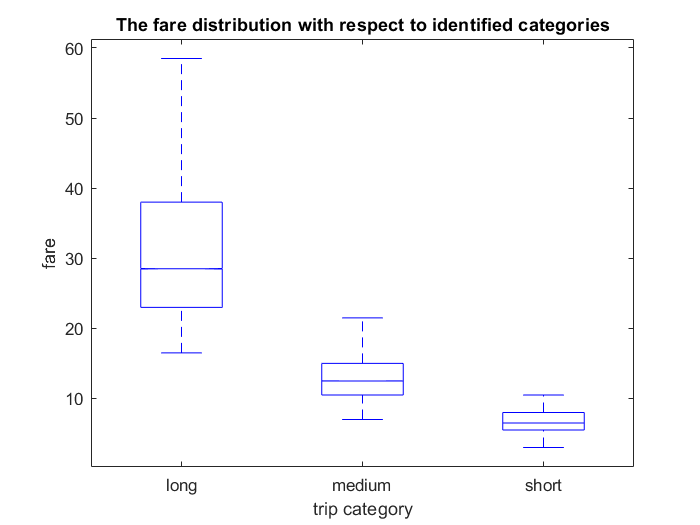

%heatmap(TaxiData,"PickupRegion","DropOffRegion",'ColorVariable',"Fare","ColorMethod","mean")
TD1=rmoutliers(TaxiData(TaxiData.idxN=="long",:),'percentiles',[0.5, 99.25],"DataVariables","Fare");
TD2=rmoutliers(TaxiData(TaxiData.idxN=="medium",:),'percentiles',[0.25, 99.75],"DataVariables","Fare");
TD3=rmoutliers(TaxiData(TaxiData.idxN=="short",:),'percentiles',[0.25, 99.75],"DataVariables","Fare");
TaxiData=vertcat(TD1,TD2,TD3);
clear TD1 TD2 TD3
boxplot(TaxiData.Fare,TaxiData.idxN,'Notch','on',"OutlierSize",5,"Colors","b","BoxStyle", ...
    "outline","Symbol",'r.')
xlabel('trip category');
ylabel('fare');
title('The fare distribution with respect to identified categories')

- As it is possible to notice, the fare in Category1 has an asimetric distribution with significant variation. Next we will delete outliers with respect of the rate fixed for the trips.

TT1=rmoutliers(TaxiData(TaxiData.RateCode=="Group",:),'mean',"DataVariables","Fare");
TT2=rmoutliers(TaxiData(TaxiData.RateCode=="JFK",:),'mean',"DataVariables","Fare");
TT3=rmoutliers(TaxiData(TaxiData.RateCode=="Nassau",:),'median',"DataVariables","Fare");
TT4=rmoutliers(TaxiData(TaxiData.RateCode=="Negotiated",:),'mean',"DataVariables","Fare");
TT5=rmoutliers(TaxiData(TaxiData.RateCode=="Newark",:),'mean',"DataVariables","Fare");
TT6=rmoutliers(TaxiData(TaxiData.RateCode=="Standard",:),'mean',"DataVariables","Fare");

TaxiData=vertcat(TT1,TT2,TT3,TT4,TT5,TT6);
clear TT1 TT2 TT3 TT4 TT5 TT6


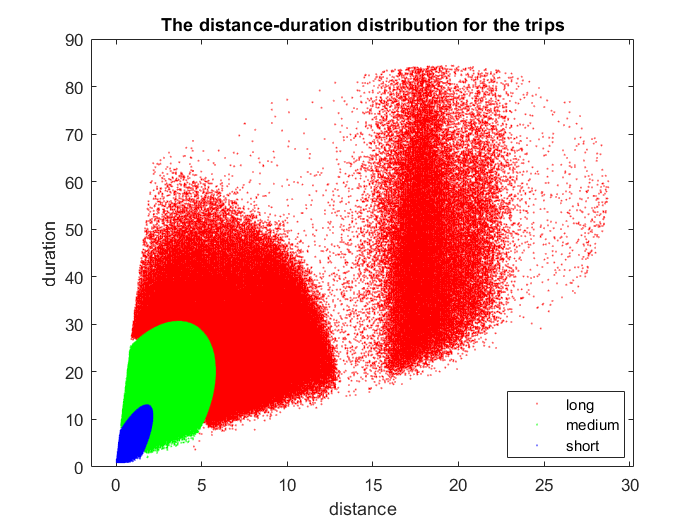

gscatter(TaxiData.Distance,TaxiData.Duration,TaxiData.idxN,[],'.',1)
xlabel('distance')
ylabel('duration')
title('The distance-duration distribution for the trips')

rng(10); % For reproducibility
gmm=[TaxiData.Distance,TaxiData.Duration];
options = statset('MaxIter',150);
gm=fitgmdist(gmm,4,'Options',options);
TaxiData.idxFare=cluster(gm,gmm);
TaxiData.PDF2=pdf(gm,gmm);
TaxiData=TaxiData(TaxiData.PDF2>2.5e-06,:);
TaxiData.idx=categorical(TaxiData.idxFare);


tab1=groupsummary(TaxiData,"idx","mean","Fare");
tab1=sortrows(tab1,"mean_Fare",'descend');
D={char(tab1.idx(1));char(tab1.idx(2));char(tab1.idx(3));char(tab1.idx(4))};
TaxiData.idx=reordercats(TaxiData.idx,D);
TaxiData.idx=renamecats(TaxiData.idx,{'JFKairport','LaGuardia','Manhatten2','Manhettan1'});

 TK1=rmoutliers(TaxiData(TaxiData.idx=="JFKairport",:),'mean',"DataVariables","Fare");
 TK2=rmoutliers(TaxiData(TaxiData.idx=="LaGuardia",:),'mean',"DataVariables","Fare");
 TK3=rmoutliers(TaxiData(TaxiData.idx=="Manhatten2",:),'mean',"DataVariables","Fare");
 TK4=rmoutliers(TaxiData(TaxiData.idx=="Manhettan1",:),'mean',"DataVariables","Fare");
 
 TaxiData=vertcat(TK1,TK2,TK3,TK4); clear  TK1 TK2 TK3 TK4;


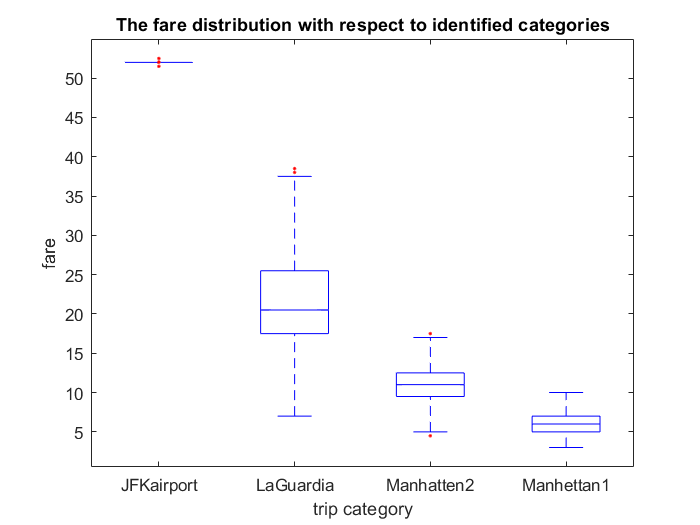

boxplot(TaxiData.Fare,TaxiData.idx,'Notch','on',"OutlierSize",5,"Colors","b","BoxStyle", ...
    "outline","Symbol",'r.')
xlabel('trip category');
ylabel('fare');
title('The fare distribution with respect to identified categories')

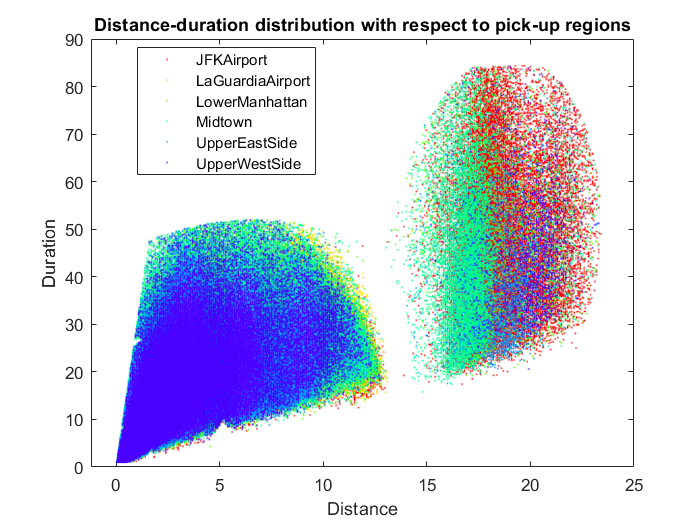

  gscatter(TaxiData.Distance(TaxiData.PickupRegion~="other"),TaxiData.Duration(TaxiData.PickupRegion~="other"),TaxiData.PickupRegion(TaxiData.PickupRegion~="other"),[],".",2);
  %gscatter(TaxiData.Distance,TaxiData.Duration,TaxiData.PickupRegion,[],".",2);
  xlabel('Distance')
  ylabel('Duration')
  title('Distance-duration distribution with respect to pick-up regions')

 
%   gscatter(TT1.Distance(TT1.DropOffRegion~="other"),TT1.Duration(TT1.DropOffRegion~="other"),TT1.DropOffRegion(TT1.DropOffRegion~="other"),[],".",2);
%   xlabel('Distance')
%   ylabel('Duration')
%   title('Distance-duration distribution with respect to drop-off regions')

% heatmap(TT1,"PickupRegion","DropOffRegion",'ColorVariable',"Fare","ColorMethod","mean")

H2=(1-height(TaxiData)/2735703)*100
TaxiFeatures=TaxiData;
clear TaxiData tab gm gmm gmN gmmN B h1 h2 TTK1 D tab1 H1 H2

H2 = 3.0597

save TaxiDataClean TaxiFeatures pathToSave

## Features 

TaxiFeatures=removevars(TaxiFeatures, {'idx','PayType','idxN','RateCode'});
TaxiFeatures.BinPickupTime=dateshift(TaxiFeatures.PickupTime,"start","hour");
TaxiFeatures.BinDropoffTime=dateshift(TaxiFeatures.DropoffTime,"start","hour");
TaxiFeatures=removevars(TaxiFeatures, {'PickupTime','DropoffTime'});

pick=groupsummary(TaxiFeatures,["PickupRegion","BinPickupTime"],"mean",["Distance","Duration","Fare","AveSpeed","TotalCharge","idxDistance","idxFare"]);
pick = sortrows(pick,'BinPickupTime','ascend');
drop=groupsummary(TaxiFeatures, ["DropOffRegion","BinDropoffTime"]);
drop = sortrows(drop,'BinDropoffTime','ascend');

% Join tables
Data = outerjoin(pick,drop,'LeftKeys',{'PickupRegion','BinPickupTime'},...
    'RightKeys',{'DropOffRegion','BinDropoffTime'},'MergeKeys',true);
Data = movevars(Data, 'GroupCount_drop', 'Before', 'mean_Distance');

Data.Properties.VariableNames{1} = 'Region';
Data.Properties.VariableNames{2} = 'BinTime';
Data.Properties.VariableNames{3} = 'PickupCount';
Data.Properties.VariableNames{4} = 'DropoffCount';

**We will concentrate our attention only on demand prediction around Manhattan (Low Manhattan, Midtown, Upper East Side, Upper West Side ) and the airports (JFK and LaGuardia). Therefore if the pickup region and drop-off region are not among the regions of interess the data will be excluded from the dataset. **

Data.Region=removecats(Data.Region,'other');
Data = Data(~ismissing(Data.Region),:);


% Fill missing data
Data.DropoffCount = fillmissing(Data.DropoffCount,'constant',0);

% Remove missing data
Data=Data(~ismissing(Data.PickupCount),:);
Data.NetPickups=Data.PickupCount-Data.DropoffCount;
Data = movevars(Data, 'NetPickups', 'Before', 'mean_Distance');
Data.Properties.VariableNames{6} = 'AveDistance';
Data.Properties.VariableNames{7} = 'AveDuration';
Data.Properties.VariableNames{8} = 'AveFare';
Data.Properties.VariableNames{9} = 'AveSpeed';
Data.Properties.VariableNames{10} = 'AveTotalCharge';
Data.Properties.VariableNames{11} ='AveCodeDistance';
Data.Properties.VariableNames{12} ='AveCodeFare';

clear drop pick TaxiFeatures
save TaxiDataSummary Data pathToSave

load TaxiDataSummary Data

## Features set 

Let us introduce a set of features which would be used for the predictive model construction. First, we suppose that in different regions demand depends on time of day, day of week, day of month, and holidays. Thus, we add four features, namely:

- time of day

Data.TimeOfDay = hours(timeofday(Data.BinTime));

- day of week

Data.DayOfWeek = categorical(day(Data.BinTime,"name"));
Data.DayOfWeek=reordercats(Data.DayOfWeek,{'Monday';'Tuesday';'Wednesday';'Thursday';'Friday';'Saturday';'Sunday'});

- day of month

Data.DayOfMonth =day(Data.BinTime);

- month of year

Data.MonthOfYear = categorical(month(Data.BinTime,'name'));
Data.MonthOfYear=reordercats(Data.MonthOfYear, ...
    {'January','February','March','April','May','June', ...
    'July','August','September','October','November','December'});

- day of year

Data.DayOfYear =day(Data.BinTime,"dayofyear");

- holiday

BankHolidays = Holidays('2015 Bank Holidays');
BankHolidays.Date = datetime(BankHolidays.Date,'InputFormat','MM/dd/yy','Format','yyyy-MM-dd');
BankHolidays.DayOfYear=day(BankHolidays.Date,"dayofyear");
Data.IsHoliday=ismember(Data.DayOfYear,BankHolidays.DayOfYear);
Data.NotWeekEnd=ismember(Data.DayOfWeek,{'Monday','Tuesday','Wednesday','Thursday','Friday'});

- some additional variables

Data.ProffCode=Data.AveCodeFare.*Data.AveCodeDistance;
Data.Tempo=Data.AveSpeed.^(-1);
avTemp=mean(Data.Tempo); RangeTemp=std(Data.Tempo);
Data.Tempo=10*(Data.Tempo-avTemp)/RangeTemp;
Data.Intencity=10*Data.AveDuration.^(-1);
Data.D=Data.AveDistance.^(-1);
Data.F=Data.Tempo.*Data.Intencity;

[indx, TD, DW]=findgroups(string(Data.TimeOfDay),string(Data.DayOfWeek));
Data.TD=strcat(TD(indx),"-",DW(indx));



### A categorical response feature

**Minimum Redundancy Maximum Relevance (MRMR) Algorithm**

Data.Demand=discretize(Data.NetPickups,[-inf,0,15,+inf],"categorical",["Low","Medium","High"]);


tbl=Data(:,{'Region', 'AveDistance','AveDuration', ...
    'AveSpeed','ProffCode', ...
    'AveCodeDistance','NotWeekEnd',...
    'TimeOfDay', ...
    'DayOfWeek', 'IsHoliday','DayOfMonth', ...
    'MonthOfYear', ...
    'Tempo','Intencity', ...    
    'D',  ...
    'F' ...
    });
rng(10);
[idx, scores] = fscmrmr(tbl,Data.Demand);
tbl.Properties.VariableNames(idx);
sum(scores(idx))
Data1=tbl;
Data1.Demand=Data.Demand;
close all
clf
bar(scores(idx))
xlabel('Predictor rank')
ylabel('Predictor importance score')
xticklabels(strrep(tbl.Properties.VariableNames(idx),'_','\_'))
xtickangle(45)


%Data.DayOfWeek=reordercats(Data.DayOfWeek,B);
heatmap(Data,"Region","DayOfWeek",'ColorVariable','NetPickups',"ColorMethod","mean",'ColorMap', jet(100))
save DataForAnalysis Data1 pathToSave

### Datasets for training and testing

Now we split the dataset for traing and testing. To ensure a random flip of initial data we set the random number generator seed to 10. Using `cvpartition` function we separate 20% of the data set for testing later on, and create the training data. 

rng(10);
DataPartitions = cvpartition(height(Data1),"HoldOut",0.2);

ans = 0.5420

%test dataset
DataTestIdx = test(DataPartitions); 
DataTest = Data1(DataTestIdx,:);

%training dataset
DataTrainIdx = training(DataPartitions); 
DataTrain = Data1(DataTrainIdx,:); 


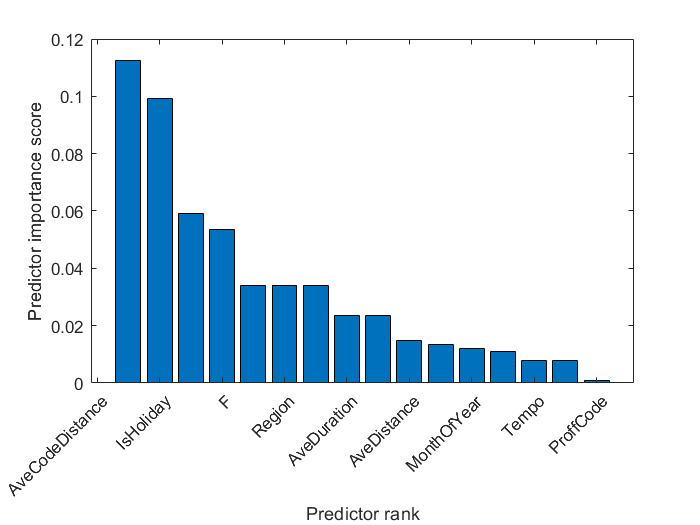

[modelStruct1, validationAccuracyModelOne] = FirstClassifier(DataTrain);

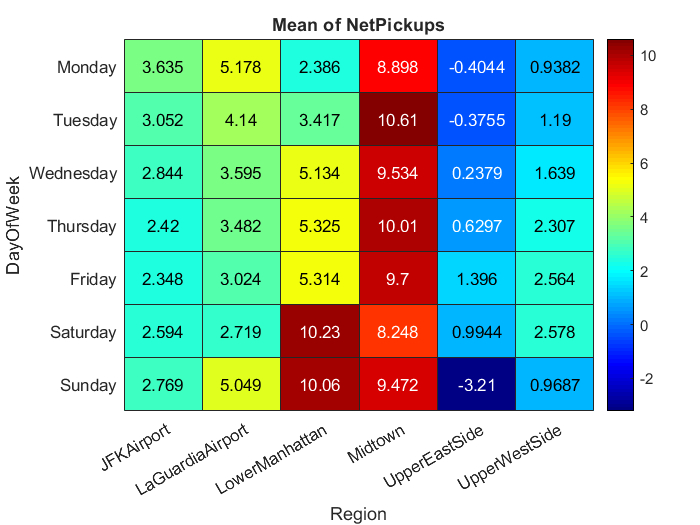

fprintf('Validation Accuracy is  %f   \n',validationAccuracyModelOne)
myModelOne = modelStruct1.ClassificationTree.ModelParameters;

yActual=DataTest.Demand;

yPredicted=modelStruct1.predictFcn(DataTest);
plotconfusion(yActual,yPredicted)
%t1 = cMetrics(yActual,yPredicted)

[modelStruct2, validationAccuracyModelTwo] = SecondClassifier(DataTrain);
fprintf('Validation Accuracy is  %f   \n',validationAccuracyModelTwo)
myModelOne = modelStruct1.ClassificationTree.ModelParameters;
yActual=DataTest.Demand;
yPredicted=modelStruct2.predictFcn(DataTest);
plotconfusion(yActual,yPredicted)
%t2= cMetrics(yActual,yPredicted)

function [t,a] = cMetrics(ytrue,ypred)
% create a table where each variable is the output of a metric function 
t = [precision(true,ypred), ...
     recall(ytrue,ypred), ...
     fallout(ytrue,ypred), ...
     specificity(ytrue,ypred), ...
     f1(ytrue,ypred)];

Validation Accuracy is  0.706092   


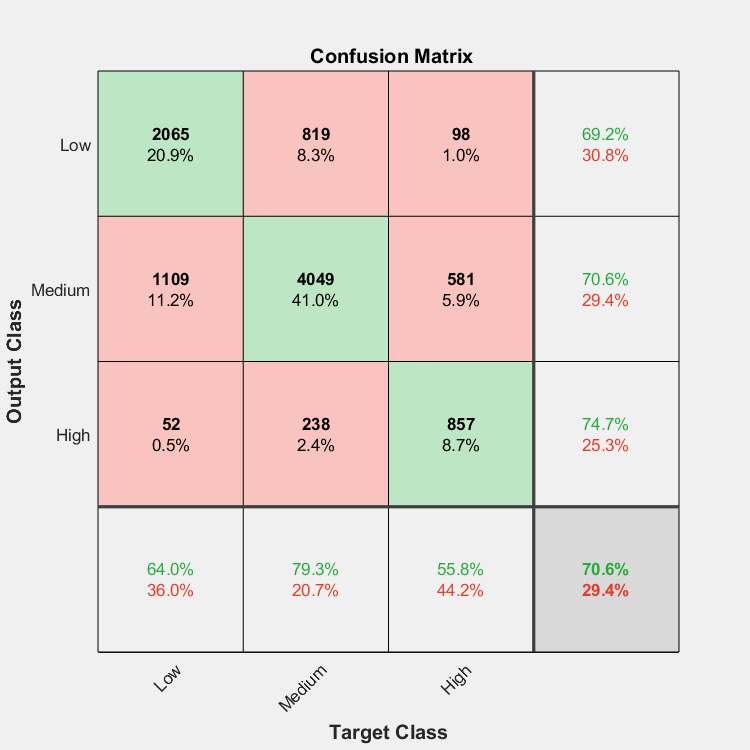


% Compute accuracy and write the percentage to the screen
a = accuracy(ytrue,ypred);
fprintf('Accuracy = %0.2f%%',a*100);


% Compute average of each metric across all classes
avg = mean(t{:,:},1);

% Categories are in alphabetical order by default

Validation Accuracy is  0.673743   


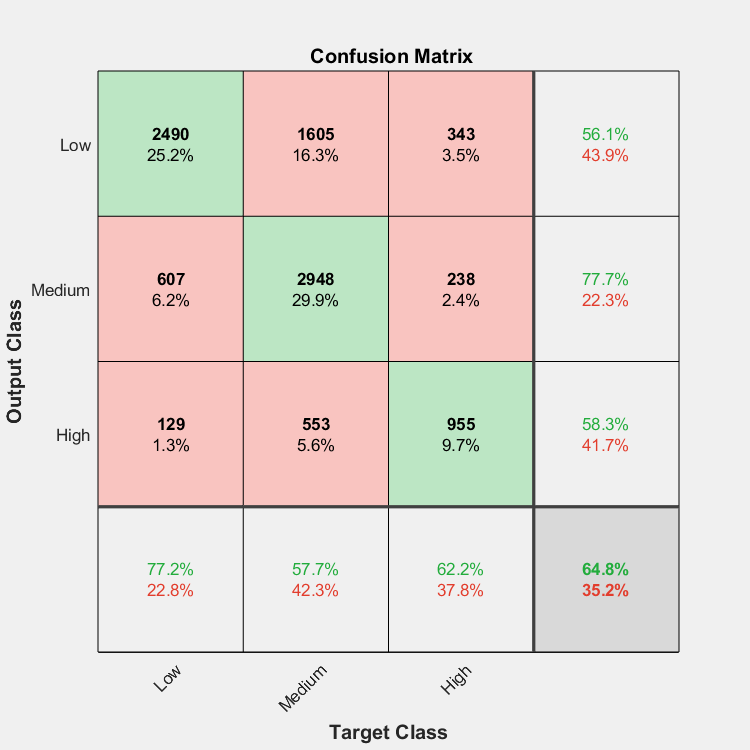

% Place ytrue classes in the same order as rows in t
ytrue = reordercats(categorical(ytrue),t.Properties.RowNames);

% Count the number of occurrences of each class

wt = countcats(ytrue);

% Compute weighted average of each metric across all classes
% eqn: wtavg = sum(metric(i) * wt(i) / total number of labels)
wtavg = sum(t{:,:}.*wt/sum(wt),1);
tavg = array2table([avg;wtavg], ...
    "VariableNames",["Precision","Recall","Fallout","Specificity","F1"],...
    "RowNames",["Avg","WgtAvg"]);

% Add table tavg to the bottom of table t
t = [t;tavg];    
end

function t = rMetrics(ytrue,ypred)
% create a table from the outputs of each metric function
t = [mae(ytrue,ypred),...
     mse(ytrue,ypred),...
      rmse(ytrue,ypred),...
      Rsq(ytrue,ypred)];
 end
